# viconExtract

run to open gui

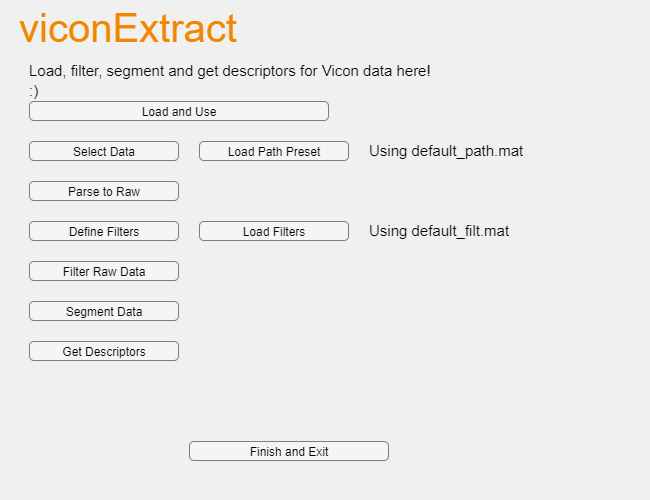

addpath(genpath(pwd));  % PWD maximum depth is ...\viconExtract to run
vesettings = importsettings();
ve_gui = viconExtract_gui();

Runtime settings

function vesettings = importsettings()
    vesettings = struct('dontuse', 'dontuse');

    % import_overrideallows importing and using of unknown/invalid .mat files
    vesettings.import_override = false;     % default is false

    % forceplatez_override forces program to use existing forceplate_force_z for segmentation
    % override may cause unintended/faulty behavior from GRFSegment
    vesettings.forceplatez_override = true;    % default is true
    
    vesettings = rmfield(vesettings, 'dontuse');
end